**Data**

x = [5  10  15  20  25  30  35  40  45  50];
y = [17  24  31  33  37  37  40  40  42  41];

**Plot data**

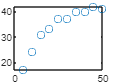

plot(x,y,'o')

**Transform data**

new_x = log10(x);
new_y = log10(y);

**Perform linear regression & plot dataset + fitted line**

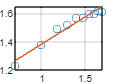

a =     0.3851    0.9980


r2 = 0.9553

[a,r2] = linregr(new_x,new_y)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 10^a(2) %10^a0

alpha = 9.9529

beta = a(1) % a1

beta = 0.3851

**Plot the original data with the best fit nonlinear curve**

xx = 5 : 0.1 : 50

xx =     5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000    6.1000    6.2000    6.3000    6.4000    6.5000    6.6000    6.7000    6.8000    6.9000    7.0000    7.1000    7.2000    7.3000    7.4000    7.5000    7.6000    7.7000    7.8000    7.9000    8.0000    8.1000    8.2000    8.3000    8.4000    8.5000    8.6000    8.7000    8.8000    8.9000    9.0000    9.1000    9.2000    9.3000    9.4000    9.5000    9.6000    9.7000    9.8000    9.9000


yy = alpha * xx.^beta

yy =    18.4973   18.6389   18.7788   18.9170   19.0537   19.1888   19.3224   19.4545   19.5852   19.7146   19.8426   19.9693   20.0947   20.2189   20.3419   20.4637   20.5844   20.7039   20.8224   20.9398   21.0561   21.1714   21.2858   21.3991   21.5115   21.6230   21.7336   21.8433   21.9521   22.0600   22.1671   22.2734   22.3789   22.4836   22.5876   22.6907   22.7932   22.8948   22.9958   23.0961   23.1957   23.2946   23.3928   23.4904   23.5874   23.6837   23.7794   23.8745   23.9689   24.0628


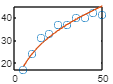

plot(x, y, 'o', xx, yy, '-')

**Predict the value of y for the given x**

xtest = 22

xtest = 22

predict_y = alpha * xtest.^beta

predict_y = 32.7255